## Homework 3

**2411374 朱灏轩**

### Question

Use Verlet Algorithm to solve the pendulum problem:

- Initial velocity $v_0=0$, initial angle $\theta_0=\pi/4$, find out the angle and angular velocity in window $[0,2000]$ with an interval of $0.2$.

- Plot the trajectory of angular velocity ~ angle in the phase space.

- Display the total energy as a function of time.


$$$\left\{ \begin{array}{l}
\theta_i = \theta_{i-1} + hv_{i-\frac{1}{2}}, \quad \quad \quad i=1,2,\cdots,\frac{T}{h}\\
v_{i+\frac{1}{2}} = v_{i-\frac{1}{2}}-h\sin\theta_i, \quad \theta_0=\frac{\pi}{4},\ T=2000,\ h=0.2 \\
\theta_0=\theta_0 \\ 
v_{\frac{1}{2}} = -\frac{h}{2}\sin\theta_0
\end{array}\right.$$$


**Tips**

Tip 1: Use `v=zeros(N, 1)` to initialize $\theta
$, $v$, $t$.

Tip 2: Use `for i = 1:N` to do the loop.

Tip 3: Use the following program structure.

- Initialize variables

- Initialize $\theta_0$, $v_{\frac{1}{2}}$

- Define $\theta_i$, $v_{i+\frac{1}{2}}$ recursively

Tip 4: Use the angle and angular velocity of the same moment to calculate the total energy and to plot the phase space, $v_i=\frac{1}{2}\left( v_{i+\frac{1}{2}} + v_{i-\frac{1}{2}} \right)$.

### Solution

根据题设信息设定程序变量

% initialize variables
% params init
v_0 = 0;
theta_0 = pi / 4;
T = 2000;
h = 0.2;

根据给定的采样时间范围以及采样时间间隔生成$\theta
$，$v$，$t$的数组

% init var arrays
t = 0:0.2:2000;
v_midi = zeros(size(t));
theta = zeros(size(t));

由 $v_{\frac{1}{2}} = -\frac{h}{2}\sin\theta_0$ 及题设条件，设定数组的第一个元素，用于后续迭代循环

% initialize theta_0 and v_mid0
v_midi(1) = -h / 2 * sin(theta_0);
theta(1) = theta_0;

进行迭代，求解各采样点处的单摆运动状态

% define theta_i and v_midi recursively
[~, max_i] = size(t);
for i = 2:max_i
    theta(i) = theta(i-1) + h * v_midi(i-1);
    v_midi(i) = v_midi(i-1) + h * (-sin(theta(i)));
end

在对单摆进行分析时，需要 $\theta$，$v
$ 的采样在同一时间点 $t$ 处进行，根据$v_i=\frac{1}{2}\left( v_{i+\frac{1}{2}} + v_{i-\frac{1}{2}} \right)$，将程序中的 `v_midi `数组转换至数组 `t` 对应的采样点

% align v with theta to the same sampling points in t
v_next_midi = circshift(v_midi, -1);
v_next_midi = v_next_midi(1:end-1);
v_form_midi = v_midi(1:end-1);
v = (v_form_midi + v_next_midi) ./ 2;
v = [v_0, v]; % concatenate v_i

至此，已经通过 Verlet 算法得到了单摆在所有采样时间点处的角度 $\theta$ 及角速度 $v$，绘制两者在相空间中的关系图

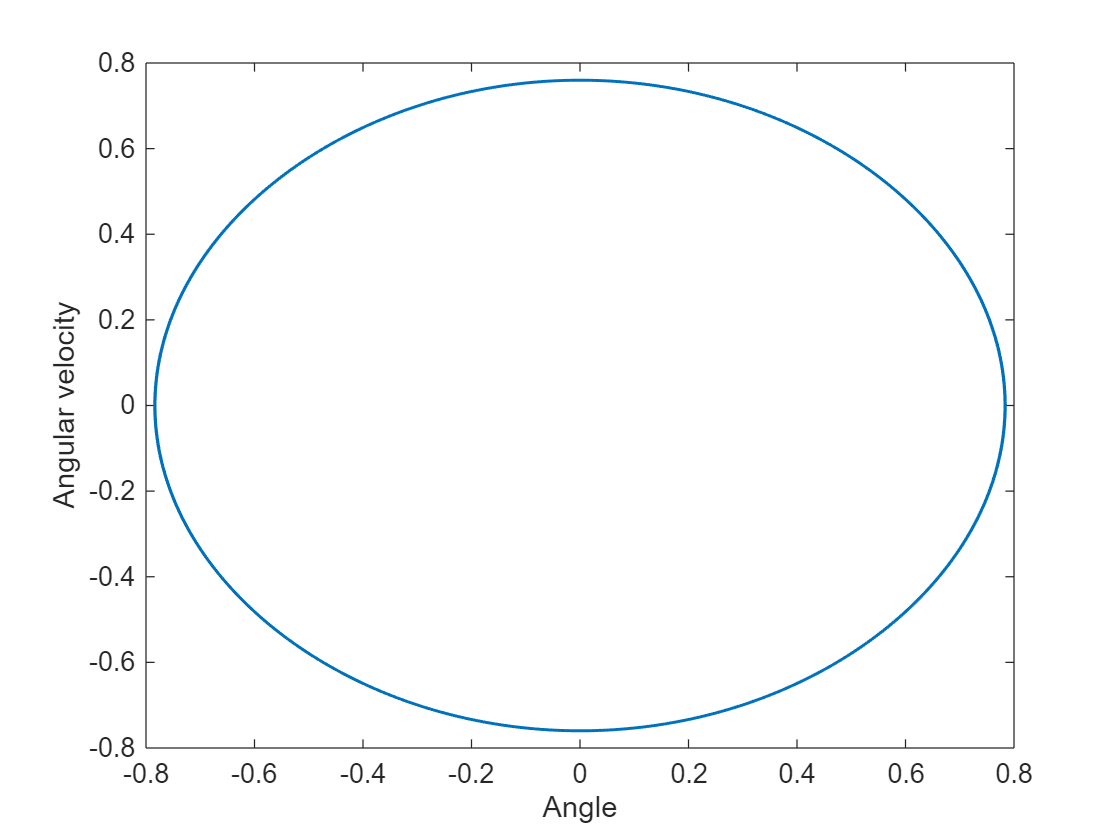

% plot the trajectory of angular velocity ~ angle in the phase space
figure;
plot(theta, v);
xlabel("Angle");
ylabel("Angular velocity");

局部放大图像

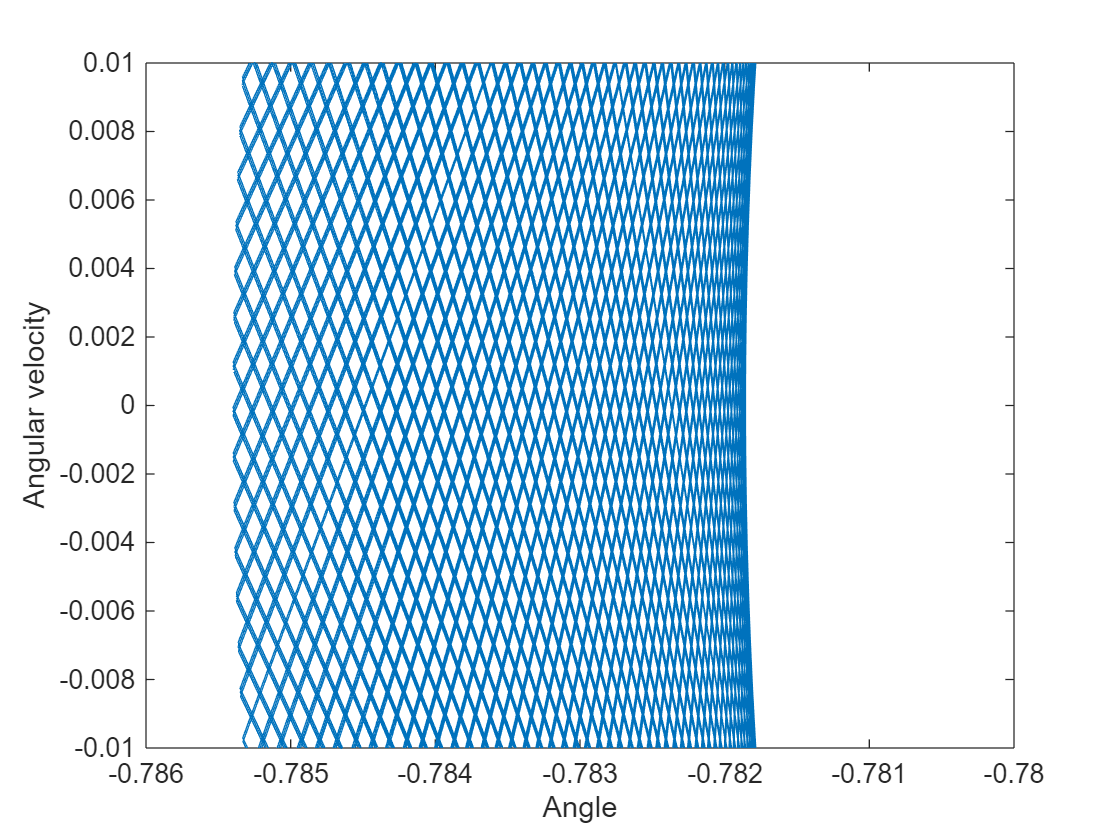

% plot the trajectory of angular velocity ~ angle in the phase space
figure;
plot(theta, v);
xlabel("Angle");
ylabel("Angular velocity");
xlim([-0.786, -0.78]);
ylim([-0.01, 0.01]);

由上图可见计算结果在一个较小范围内波动

不妨令 $\frac{1}{\omega}$ 为单位时间，$\frac12mL^2\omega^2$ 为单位能量，单摆的总能量如下


$$\begin{array}{l}
\text{E}& =\frac{1}{2}mv^{2}+V(r) \\
&=\frac{1}{2}m\left(L\theta^{\prime}\right)^{2}-mgL\cos\theta \\
&=\frac{1}{2}mL^{2}\left( \theta^{\prime 2}-\frac{2 g}{L}\cos\theta \right) \\
&=\frac{1}{2}mL^{2}\left(\theta^{\prime2}-2\omega^{2}\cos\theta\right) \\
&=\theta^{\prime2}-2\cos\theta 
\end{array}$$


由上述推导结果，可以由角度 $\theta
$ 及 角速度 $v
$ 计算单摆总能量，并绘制能量在题设时间范围内的变化情况

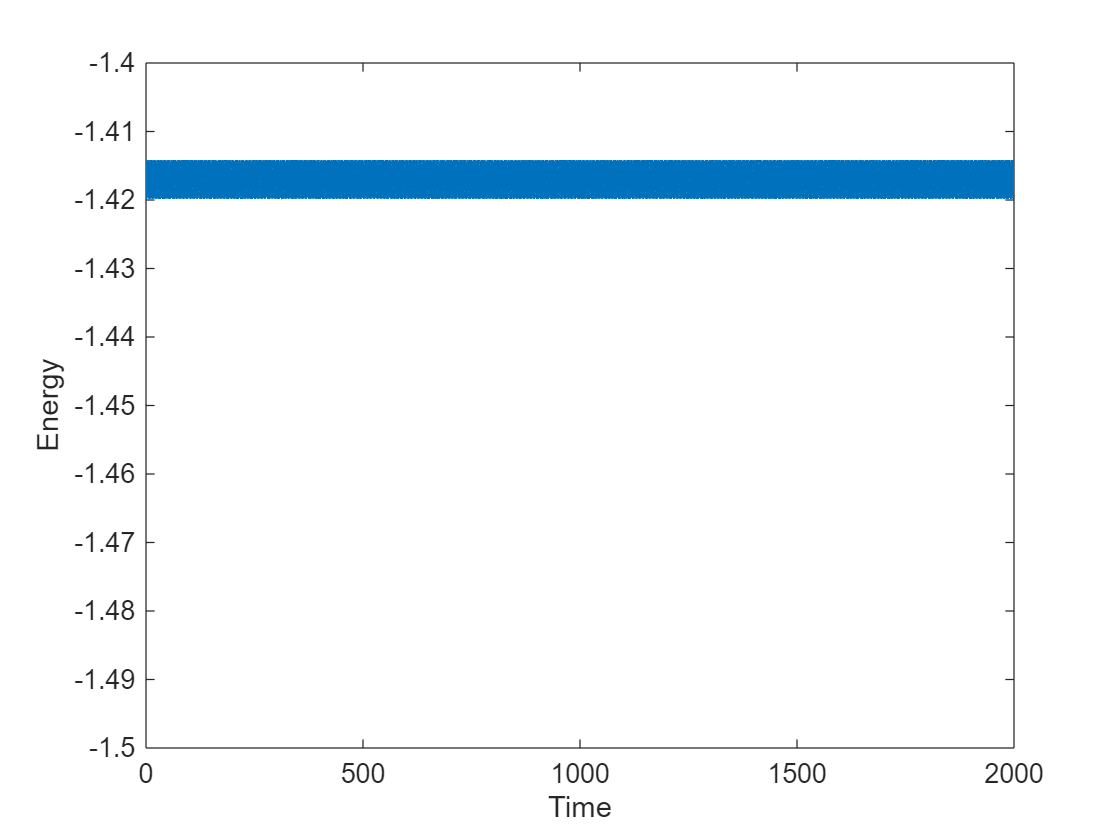

% Calculate energy and plot
E = v .^ 2 - 2 * cos(theta);
figure;
plot(t, E);
xlabel("Time");
ylabel("Energy");
ylim([-1.5, -1.4]);

局部放大图像

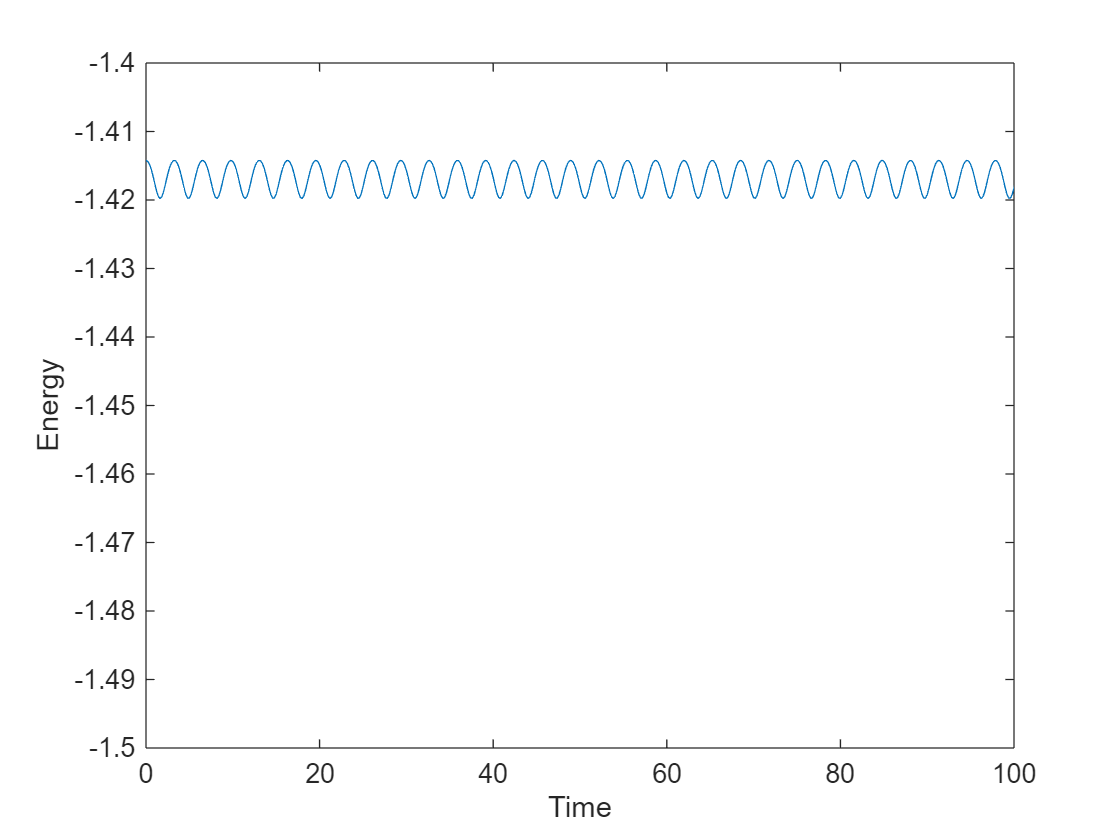

figure;
plot(t, E);
xlabel("Time");
ylabel("Energy");
xlim([0, 100]);
ylim([-1.5, -1.4]);

由上述能量变化图像可知，Verlet 算法求解结果中的系统能量虽有波动，但能够保持不变的趋势，符合物理推导结果。